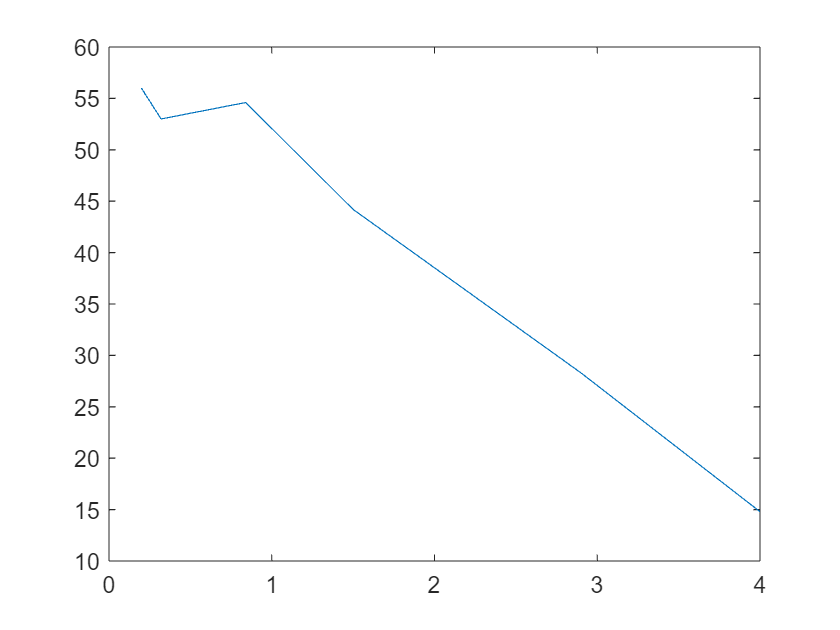

%Williams data
%clearing mem
clear all
clf

%declaring symbolic variables
syms x

%known points
mol = [0.199, 0.32, 0.84, 1.5, 2.9, 4]; %mol% values
iso = [56, 53, 54.6, 44.2, 28.3, 14.8]; %area under Fe3+ sextets
y_err = [3.11, 2.83, 1.41, 1.41, 0.57, 0.3]; %error values on area

plot(mol,iso)

%perfoming plot of points
%errorbar(mol ,iso ,y_err, "^",'MarkerFaceColor','#4DBEEE','MarkerSize',3)
%hold on %future plots on same graph

%calculating line of best fit
%p = polyfit(mol,iso,1);
%f(x) = x*p(1) + p(2); %straight line
% Actual straight line that takes into account error bars from Python
% fitter
%f(x) = -11.881177*x + 62.40587;
%fd(x) = -10.8596*x + 67.879; %Dormann
%fb(x) = -16.21*x + 65.51; %Bingham
%fs(x) = -16.11*x + 69.29; %SLS
%fn(x) = -12.78*x + 65.68; %NBS
%fc(x) = -28.85*x + 97.45; %CaZnSF


%plotting straignt line
%fplot(f(x),"r--")

%fplot(fd(x),"g--")
%fplot(fb(x),"b--")
%fplot(fs(x),"--")
%fplot(fn(x),"--")
%fplot(fc(x),"--")
%hold off %end plotting

%setting x & y limits
%xlim([0 4])
%ylim([0 60])

%beautifying curve
%ax = gca;
%ax.XAxisLocation = "origin";
%ax.YAxisLocation = "origin";
%box off;

%labelling graph
%xlabel("Fe_{2}O_{3} content [mol%]");
%ylabel("Area under Fe^{3+} sextets [%]");
%title('Fe^{3+} sextet area Vs. Fe_{2}O_{3} content in SLS glasses (Williams data [14])')
%title('Fe^{3+} sextet area Vs. Fe_{2}O_{3} content in SLS glasses (Williams data)')
%title('Fe^{3+} sextet area Vs. Fe_{2}O_{3} content in glasses (Third-party glasses)')
%title('Fe^{3+} sextet area Vs. Fe_{2}O_{3} content in glasses (All glasses)')
%legend("Data points","Williams","Dormann","Bingham","SLS","NBS","CaZnSF","Location","southwest")
%legend("Data points","Best fit","Location","southwest")

%Williams data vs SLS data
%clearing mem
clear all
clf

%declaring symbolic variables
syms x

%known points Williams
mol = [0.199, 0.32, 0.84, 1.5, 2.9, 4]; %mol% values
iso = [56, 53, 54.6, 44.2, 28.3, 14.8]; %area under Fe3+ sextets
y_err = [3.11, 2.83, 1.41, 1.41, 0.57, 0.3]; %error values on area

%perfoming plot of points
errorbar(mol ,iso ,y_err, "^",'MarkerFaceColor','#4DBEEE','MarkerSize',3)
hold on %future plots on same graph

%calculating line of best fit
p = polyfit(mol,iso,1);
%f(x) = x*p(1) + p(2); %straight line
% Actual straight line that takes into account error bars from Python
% fitter
f(x) = -11.881177*x + 62.40587;
%fd(x) = -10.8596*x + 67.879; %Dormann
%fplot(fd(x))

%plotting straignt line
fplot(f(x),"r--")
%%%SLS
%known points 
mol = [1.12, 4.3]; %mol% values
iso = [51.24, 0  ]; %area under Fe3+ sextets
y_err = [2.28, 0]; %error values on area

%perfoming plot of points
errorbar(mol ,iso ,y_err, "^","MarkerEdgeColor",'#4DBEEE',"Color",'#4DBEEE','MarkerFaceColor','#4DBEEE','MarkerSize',3)
hold on %future plots on same graph

%calculating line of best fit 
p = polyfit(mol,iso,1);
p
f1(x) = x*p(1) + p(2); %straight line
fplot(f1(x),'Color','#4DBEEE',"LineStyle","--")

hold off %end plotting

%setting x & y limits
xlim([0 4])
ylim([0 60])

%beautifying curve
ax = gca;
ax.XAxisLocation = "origin";
ax.YAxisLocation = "origin";
box off;

%labelling graph
xlabel("Fe_{2}O_{3} content [mol%]");
ylabel("Area under Fe^{3+} sextets [%]");
title('Fe^{3+} sextet area Vs. Fe_{2}O_{3} content in SLS glasses (Williams data [14])')
legend("Data points","Williams","Location","southwest")

%Dormann data
%clearing mem
clear all
clf

%declaring symbolic variables
syms x

%known points
mol = [1.66, 3.46, 5.16]; %mol% values
iso = [50, 30, 12]; %area under Fe3+ sextets

%perfoming plot of points
plot(mol ,iso , "^",'MarkerFaceColor','#4DBEEE','MarkerSize',3)
hold on %future plots on same graph

%calculating line of best fit
p = polyfit(mol,iso,1);
p
f(x) = x*p(1) + p(2); %straight line

%plotting straignt line
fplot(f(x),"r--")
hold off %end plotting

%setting x & y limits
xlim([1.5 5.5])
ylim([5 50])

%beautifying curve
ax = gca;
ax.XAxisLocation = "origin";
ax.YAxisLocation = "origin";
box off;

%labelling graph
xlabel("Fe_{2}O_{3} content [mol%]");
ylabel("Area under Fe^{3+} sextets [%]");
title('Fe^{3+} sextet area Vs. Fe_{2}O_{3} content in NBS glasses (Magini & Dormann data)')
legend("Data points","Best fit","Location","southwest")

%calculating R squared value
mean = mean(iso); %calculating mean
%initialising blank Rsq sums
Rt = 0; %top
Rb = 0; %bottom
for i=1:length(iso)

    Rt = Rt + (iso(i) - f(mol(i)))^2;

    Rb = Rb + (iso(i) - mean)^2;

end

%calculating R squared value
Rsq = eval(1 - Rt/Rb)

%Bingham data
%clearing mem
clear all
clf

%declaring symbolic variables
syms x

%known points
mol = [1, 2]; %mol% values
iso = [49.3, 33.09  ]; %area under Fe3+ sextets
y_err = [2.83, 2.83]; %error values on area

%perfoming plot of points
%plot(mol ,iso , "^",'MarkerFaceColor','#4DBEEE','MarkerSize',3)
errorbar(mol ,iso ,y_err, "^",'MarkerFaceColor','#4DBEEE','MarkerSize',3)
hold on %future plots on same graph

%calculating line of best fit
p = polyfit(mol,iso,1);
p
f(x) = x*p(1) + p(2); %straight line

%plotting straignt line
fplot(f(x),"r--")

%plotting KFE williams best fit
%f1(x) = -11.881177*x + 62.40587;
%fplot(f1(x),"g--")
%f2(x) = -10.8596*x + 67.8790;
%fplot(f2(x),"b--")
%f3(x) = -10.333*x + 66.333;
%fplot(f3(x),"b--")
hold off %end plotting

%setting x & y limits
xlim([0.8 2.2])
ylim([30 55])

%beautifying curve
ax = gca;
ax.XAxisLocation = "origin";
ax.YAxisLocation = "origin";
box off;

%labelling graph
xlabel("Fe_{2}O_{3} content [mol%]");
ylabel("Area under Fe^{3+} sextets [%]");
title('Fe^{3+} sextet area Vs. Fe_{2}O_{3} content in NBS glasses (Bingham data)')
legend("Data points","Best fit","Location","southwest") 

%Research data
%clearing mem
clear all
clf

%declaring symbolic variables
syms x

%%%SLS
%known points 
mol = [1.12, 4.3]; %mol% values
iso = [51.24, 0  ]; %area under Fe3+ sextets
y_err = [2.28, 0]; %error values on area

%perfoming plot of points
errorbar(mol ,iso ,y_err, "^","MarkerEdgeColor",'#4DBEEE',"Color",'#4DBEEE','MarkerFaceColor','#4DBEEE','MarkerSize',3)
hold on %future plots on same graph

%calculating line of best fit 
p = polyfit(mol,iso,1);
p
f1(x) = x*p(1) + p(2); %straight line
fplot(f1(x),'Color','#4DBEEE',"LineStyle","--")

%%%NBS
%known points 
mol = [1.08, 4.59]; %mol% values
iso = [51.87, 7  ]; %area under Fe3+ sextets
y_err = [2.28, 2]; %error values on area

%perfoming plot of points
errorbar(mol ,iso ,y_err, "^","MarkerEdgeColor",'#D95319',"Color",'#D95319','MarkerFaceColor',"#D95319",'MarkerSize',3)

%calculating line of best fit 
p = polyfit(mol,iso,1);
p
f2(x) = x*p(1) + p(2); %straight line
fplot(f2(x),'Color',"#D95319","LineStyle","--")

%%%CaZnSF
%known points 
mol = [1.44, 2.49]; %mol% values
iso = [55.91, 25.62  ]; %area under Fe3+ sextets
y_err = [2.28, 2.28]; %error values on area

%perfoming plot of points
errorbar(mol ,iso ,y_err, "^","MarkerEdgeColor",'#FF0064',"Color",'#FF0064','MarkerFaceColor',"#FF0064",'MarkerSize',3)

%calculating line of best fit 
p = polyfit(mol,iso,1);
p
f1(x) = x*p(1) + p(2); %straight line
fplot(f1(x),'Color',"#FF0064","LineStyle","--")

hold off %end plotting

%setting x & y limits
xlim([1 5])
ylim([0 60])

%beautifying curve
ax = gca;
ax.XAxisLocation = "origin";
ax.YAxisLocation = "origin";
box off;

%labelling graph
xlabel("Fe_{2}O_{3} content [mol%]");
ylabel("Area under Fe^{3+} sextets [%]");
title('Fe^{3+} sextet area Vs. Fe_{2}O_{3} SLS/NBS/CaZnSF')
legend("SLS points","SLS fit","NBS points","NBS fit","CaZnSF points","CaZnSF fit","Location","NorthEast") 

%All
%clearing mem
clear all
clf

%declaring symbolic variables
syms x

%%%SLS
%known points 
mol = [1.12, 4.3]; %mol% values
iso = [51.24, 0  ]; %area under Fe3+ sextets
y_err = [2.28, 0]; %error values on area

%calculating line of best fit 
p = polyfit(mol,iso,1);
p

p =   -16.1132   69.2868


f1(x) = x*p(1) + p(2); %straight line
fplot(f1(x),'Color','#4DBEEE',"LineStyle","--")
hold on

%%%NBS
%known points 
mol = [1.08, 4.59]; %mol% values
iso = [51.87, 7  ]; %area under Fe3+ sextets
y_err = [2.28, 2]; %error values on area

%calculating line of best fit 
p = polyfit(mol,iso,1);
p

p =   -12.7835   65.6762


f2(x) = x*p(1) + p(2); %straight line
fplot(f2(x),'Color',"#D95319","LineStyle","--")

%%%CaZnSF
%known points 
mol = [1.44, 2.49]; %mol% values
iso = [55.91, 25.62  ]; %area under Fe3+ sextets
y_err = [2.28, 2.28]; %error values on area

%calculating line of best fit 
p = polyfit(mol,iso,1);
p

p =   -28.8476   97.4506


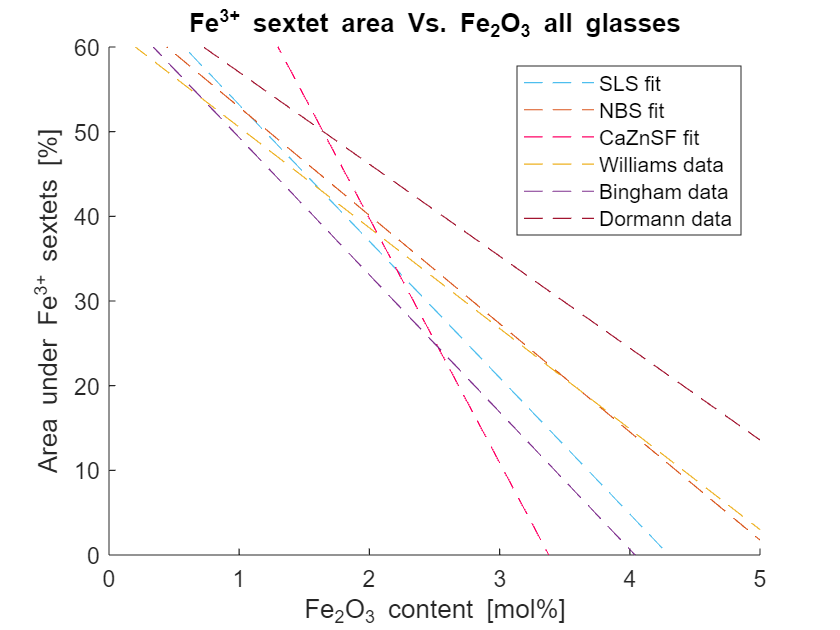

f1(x) = x*p(1) + p(2); %straight line
fplot(f1(x),'Color',"#FF0064","LineStyle","--")

%adding plots from other sources
fw(x) = -11.881177*x + 62.40587; %Williams
fb(x) = -16.21*x + 65.51; %Bingham
fd(x) = -10.8596*x + 67.879; %Dormann

fplot(fw(x),'Color',"#EDB120","LineStyle","--")

%known points for williams data
%mol = [0.199, 0.32, 0.84, 1.5, 2.9, 4]; %mol% values
%iso = [56, 53, 54.6, 44.2, 28.3, 14.8]; %area under Fe3+ sextets
%y_err = [3.11, 2.83, 1.41, 1.41, 0.57, 0.3]; %error values on area
%y_err = [5.6, 5.3, 5.46, 4.42, 2.83, 1.48]; %error values on area

%perfoming plot of points
%errorbar(mol ,iso ,y_err, "^","MarkerEdgeColor",'#EDB120',"Color",'#EDB120','MarkerFaceColor',"#EDB120",'MarkerSize',3)
%hold on %future plots on same graph


% fplot(fb(x),'Color',"#7E2F8E","LineStyle","--")
% fplot(fd(x),'Color',"#A2142F","LineStyle","--")

hold off %end plotting

%setting x & y limits
% xlim([0 5])
% ylim([0 60])

%beautifying curve
% ax = gca;
% ax.XAxisLocation = "origin";
% ax.YAxisLocation = "origin";
% box off;

%labelling graph
% xlabel("Fe_{2}O_{3} content [mol%]");
% ylabel("Area under Fe^{3+} sextets [%]");
% title('Fe^{3+} sextet area Vs. Fe_{2}O_{3} all glasses')
% legend("SLS fit", ...
%     "NBS fit", ...
%     "CaZnSF fit", ...
%     "Williams data", ...
%     "Williams error",...
%     "Bingham data", ...
%     "Dormann data",...
%     "Location","NorthEast")
% 
% legend("SLS fit", ...
%     "NBS fit", ...
%     "CaZnSF fit", ...
%     "Williams data", ...
%     "Bingham data", ...
%     "Dormann data",...
%     "Location","NorthEast")

%clearing mem
clear all
clf

%declaring symbolic variables
syms x

fw(x) = -11.881177*x + 62.40587; %Williams
fb(x) = -16.21*x + 65.51; %Bingham
fd(x) = -10.8596*x + 67.879; %Dormann
fs(x) = -16.11*x + 69.29; %SLS
fn(x) = -12.78*x + 65.68; %NBS
fc(x) = -28.85*x + 97.45; %CaZnSF


eval(solve(fw(x)==0,x))
eval(solve(fb(x)==0,x))
eval(solve(fd(x)==0,x))
eval(solve(fs(x)==0,x))
eval(solve(fn(x)==0,x))

%eval(solve(fc(x)==55,x))